cd('C:\Users\PC\Desktop\3081\Content-based-Image-Retrieval')

%CIFAR100
% rootFolder = 'cifar-100-matlab\CIFAR-100\TEST';
% categories = {'cup','dinosaur','forest','hamster'};

%COREL80
rootFolder = 'CorelDB';
categories = {'art_antiques','obj_car','sc_sunset','wl_buttrfly','bld_sculpt'};

imds = imageDatastore(fullfile(rootFolder, categories), 'LabelSource', 'foldernames');
imagesPerClass = 100;
[trainingSet, ~] = splitEachLabel(imds, imagesPerClass, 'randomize'); 

featureSet = [];
ref = [];
numImages = numel(trainingSet.Files);

% preprocess the images in the dataset and collect:
% - their SIFT features into the featureSet matrix
% - their original image ID into the ref vector
for i = 1 : numImages
    I = im2gray(readimage(trainingSet,i));
    I = imresize(I, [256 256]); % can try without this
    sift = detectSIFTFeatures(I).selectStrongest(25);
    [features, sift_points] = extractFeatures(I, sift);
    featureSet = cat(2, featureSet, features.');
    ref = cat(2, ref, repmat([i], 1, size(features,1)));
end


% construct LSH hash tables for featureSet
cd('vLSH')

% Tune hyperparameters
% Q = 144;  % # of queries
K = 32;   % # of nearest neighbors to search for each query
L = 10;   % # of tables
M = 25;   % # of dimensions at projection space
W = 1000; % bucket width
T = 10;   % # of additional probing bins

% Construct index tables
lshStruct = lshConstruct(featureSet, L, M, W);

Creating table 1/10
	Projecting data...
	15229 buckets
	min / max size: 1 / 27
	mean / median: 1.106901e+00 / 1
Creating table 2/10
	Projecting data...
	15187 buckets
	min / max size: 1 / 18
	mean / median: 1.109962e+00 / 1
Creating table 3/10
	Projecting data...
	15237 buckets
	min / max size: 1 / 44
	mean / median: 1.106320e+00 / 1
Creating table 4/10
	Projecting data...
	14897 buckets
	min / max size: 1 / 43
	mean / median: 1.131570e+00 / 1
Creating table 5/10
	Projecting data...
	15140 buckets
	min / max size: 1 / 12
	mean / median: 1.113408e+00 / 1
Creating table 6/10
	Projecting data...
	15309 buckets
	min / max size: 1 / 21
	mean / median: 1.101117e+00 / 1
Creating table 7/10
	Projecting data...
	15569 buckets
	min / max size: 1 / 20
	mean / median: 1.082728e+00 / 1
Creating table 8/10
	Projecting data...
	15318 buckets
	min / max size: 1 / 19
	mean / median: 1.100470e+00 / 1
Creating table 9/10
	Projecting data...
	14413 buckets
	min / max size: 1 / 34
	mean / median: 1.169569e

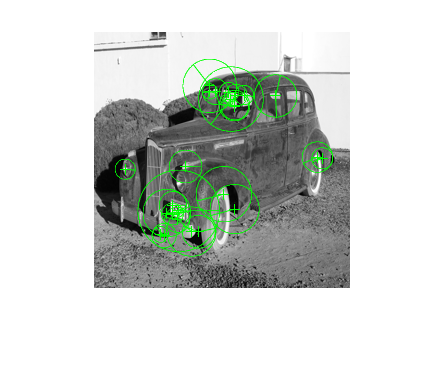

% query an input image
I = imread("car1.jpg");
I = imresize(im2gray(I), [256 256]);
figure, imshow(I); hold on;
sift = detectSIFTFeatures(I).selectStrongest(25);
[queryFeatures, valid_points] = extractFeatures(I, sift);
plot(valid_points,'showOrientation',true);


% [idsMULTIPROBE, cand_sizeMULTIPROBE, binsFound_ratiosMULTIPROBE] = lshSearch(featureSet(:, 1:Q), featureSet, lshStruct, K, T);
[idsMULTIPROBE, cand_sizeMULTIPROBE, binsFound_ratiosMULTIPROBE] = lshSearch(queryFeatures.', featureSet, lshStruct, K, T);

Retrieving candidates from table 1
	-----> 0.085557 seconds
Retrieving candidates from table 2
	-----> 0.072020 seconds
Retrieving candidates from table 3
	-----> 0.079949 seconds
Retrieving candidates from table 4
	-----> 0.072500 seconds
Retrieving candidates from table 5
	-----> 0.087123 seconds
Retrieving candidates from table 6
	-----> 0.085938 seconds
Retrieving candidates from table 7
	-----> 0.098969 seconds
Retrieving candidates from table 8
	-----> 0.092364 seconds
Retrieving candidates from table 9
	-----> 0.099481 seconds
Retrieving candidates from table 10
	-----> 0.083491 seconds
Removing duplicate candidates...
	-----> 0.002004 seconds
Performing knn search...
	-----> 0.001652 seconds
Calculating candidate sizes...
	-----> 0.008027 seconds


% convert the feature IDs into their original image IDs
oriImages = zeros(size(idsMULTIPROBE));
for i = 1 : size(idsMULTIPROBE, 1)
    for j = 1 : size(idsMULTIPROBE, 2)
        if idsMULTIPROBE(i, j)>0
          oriImages(i,j) = ref(:,idsMULTIPROBE(i, j));
        end
    end
end

% aggregate and weight the image features by their ranks 
uniqImageIds = unique(oriImages);
N = numel(uniqImageIds);
weights = zeros(N,1);
fib = zeros(1, K); fib(K-1) = 1;
for i = K-2:-1:1
   fib(i) = fib(i+1)+fib(i+2);
end

for k = 1 : N
    weights(k) = sum(sum(oriImages == uniqImageIds(k))); % unranked weighting of NNs
    % ranked weighting of NNs
%   weights(k) = sum((K + (0 : K - 1) * -1) * (oriImages == uniqImageIds(k)));  % linear
%   weights(k) = sum(flip(exp(1 : K)) * (oriImages == uniqImageIds(k))); % exponential
%   weights(k) = sum(fib * (oriImages == uniqImageIds(k))); % fibonacci
end

ranks = sortrows([weights uniqImageIds], 1, 'descend');


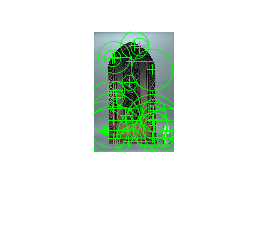

I = 256×256 uint8 matrix
   131   131   132   133   134   135   136   137   137   138   139   139   139   139   139   139   140   140   140   141   142   143   143   144   144   144   144   144   144   144   144   145   145   146   146   146   147   147   148   149   149   150   151   151   151   152   152   153   152   153
   134   134   135   136   137   138   139   140   140   141   142   142   142   142   142   142   143   143   143   144   145   146   146   147   147   147   147   147   147   147   147   148   148   149   149   149   150   150   151   152   152   153   154   154   154   155   155   155   155   155
   140   140   140   141   142   143   144   146   146   147   147   147   148   148   148   148   149   149   150   150   151   151   152   152   152   153   153   153   153   153   153   154   154   155   155   155   156   156   157   158   158   159   159   159   160   160   161   161   162   162
   147   147   147   148   149   150   151   153   153   154   154   154

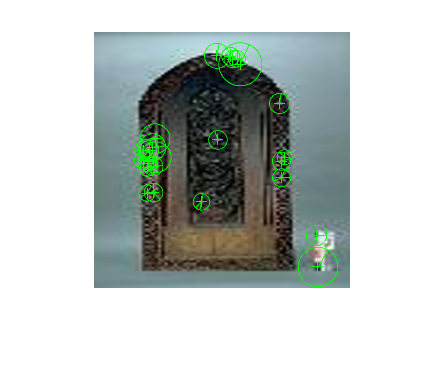

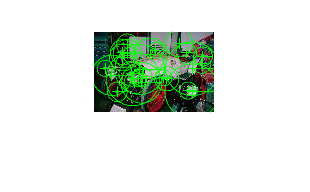

I = 256×256 uint8 matrix
   12   12   12   12   12   11   11   11   11   11   10   11   11   12   13   13   14   14   16   21   24   22   20   20   20   27   34   33   29   24   20   22   29   35   41   37   18    5    8   13   12    9    4    1    0    1    1    2    3    7
   12   12   12   12   12   11   11   11   11   11   11   11   12   13   13   14   15   14   16   21   24   22   20   20   21   27   34   33   29   24   19   20   27   32   38   34   17    5    8   12   11    8    5    2    1    3    3    4    6   10
   12   12   13   13   12   12   12   12   12   13   13   14   14   15   15   16   16   15   17   22   25   23   20   21   23   28   34   34   30   24   17   17   23   27   32   28   15    5    7   10    9    7    6    6    6    8    8    9   12   21
   13   13   14   13   13   13   13   13   14   15   15   16   17   17   18   19   18   16   18   24   27   24   21   22   26   29   34   34   33   25   15   12   16   19   21   19   10    5    5    7    6    5    8   13  

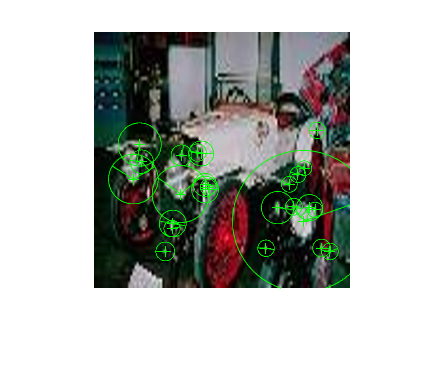

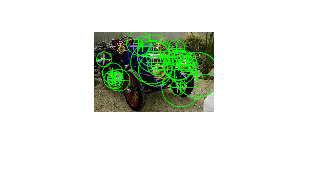

I = 256×256 uint8 matrix
    75    78    84    87    83    80    81    83    84    85    85    85    89    94    94    88    86    89    91    87    89   101   109   106   102   104   105    98    89    91    99   100    94    93    97   101   103   103    97    91    83    79    88   101   108   112   108   101   104   119
    76    79    85    88    84    81    82    84    85    86    86    86    90    95    94    88    87    90    92    88    89   101   109   106   102   104   105    98    89    91    99   100    95    94    97   101   103   103    98    93    85    81    89   101   107   111   107   100   103   117
    78    81    87    90    86    83    84    86    87    88    88    88    91    96    95    89    88    92    93    89    90   101   109   106   102   104   105    98    90    92    99   101    96    95    98   101   102   102   100    97    90    85    91   101   106   109   105    99   101   113
    82    85    91    94    90    87    87    89    90    91    91    90

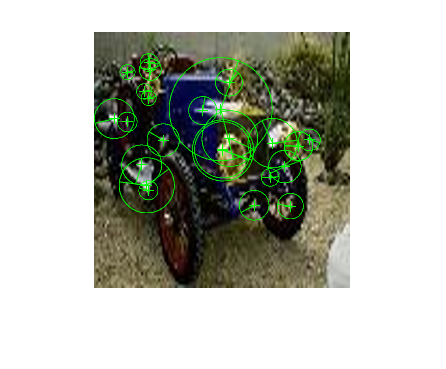

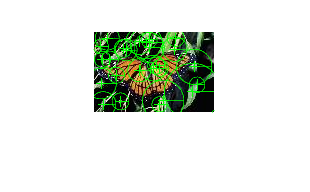

I = 256×256 uint8 matrix
     7     6     5     3     4     2     1     1     7    13     4     0    58   149   170   135    96    47    18    14    13     8     5     4     5     8    12     9     8    49   120   170   203   164    36     0   100   184   185   171   177   167    98    12     0     0     3    11    16    19
     7     6     5     3     4     3     2     2     7    12     4     1    59   148   168   133    94    46    17    13    12     8     6     4     5     9    14    11    11    54   128   171   189   152    46    13   103   174   172   158   162   153    89    11     0     0     4    10    15    18
     7     6     4     3     5     5     4     3     6    10     4     5    61   146   164   130    91    43    14    11    10     8     7     4     3     9    18    14    12    64   150   177   153   120    71    60   111   149   140   125   125   117    67     8     1     3     6     9    12    15
     7     6     3     2     6     8     7     6     5     7     4    11

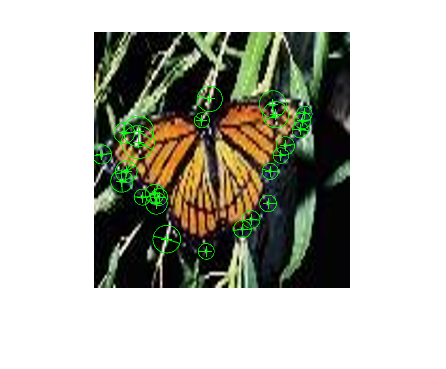

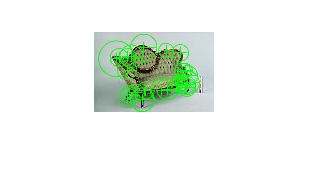

I = 256×256 uint8 matrix
   185   185   186   186   187   187   188   189   190   190   190   191   191   191   191   191   192   193   194   194   194   195   195   195   195   195   196   197   197   197   198   198   198   198   199   200   200   200   199   199   199   199   199   199   199   198   198   198   198   198
   185   185   186   186   187   187   188   189   190   190   190   191   191   191   191   191   192   193   194   194   194   195   195   195   195   195   196   197   197   197   198   198   198   198   199   200   200   200   199   199   199   199   199   199   199   198   198   198   198   198
   186   186   187   187   188   188   189   190   191   191   191   192   192   192   192   192   192   193   194   194   194   195   195   195   195   195   196   197   197   197   198   198   198   198   199   200   200   200   199   199   199   199   199   199   199   198   198   198   198   198
   187   187   188   188   189   189   190   191   192   192   192   193

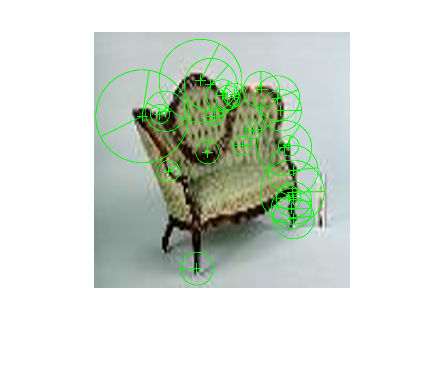

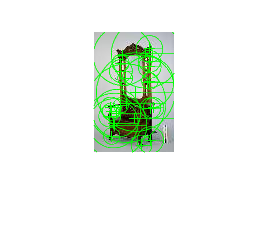

I = 256×256 uint8 matrix
   185   185   185   186   186   186   187   187   187   187   188   188   188   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189
   185   185   185   186   186   186   187   187   187   187   188   188   188   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189
   185   185   185   185   186   186   187   188   188   189   189   189   189   190   190   190   190   190   190   190   190   190   190   190   190   190   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189
   185   185   185   185   186   186   187   188   188   189   189   189

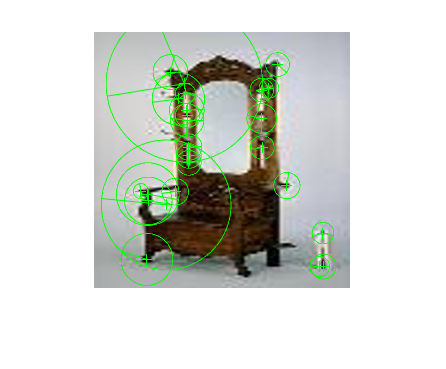

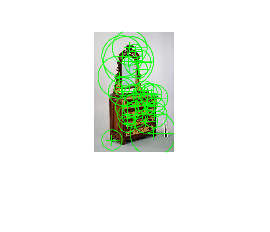

I = 256×256 uint8 matrix
   207   207   207   208   208   208   209   209   209   209   210   210   210   211   211   211   211   211   211   211   211   211   211   211   211   211   211   211   211   211   211   211   211   211   211   212   212   212   212   212   212   212   212   212   212   213   213   213   213   213
   207   207   207   208   208   208   209   209   209   209   210   210   210   211   211   211   211   211   211   211   211   211   211   211   211   211   211   211   211   211   211   211   211   211   211   212   212   212   212   212   212   212   212   212   212   213   213   213   213   213
   207   207   207   208   208   208   208   209   209   210   211   211   211   211   211   211   212   212   212   212   212   212   211   211   211   211   211   211   211   211   211   211   212   212   212   212   212   212   212   212   212   212   213   213   213   213   213   213   213   213
   207   207   207   208   208   208   208   209   209   210   211   211

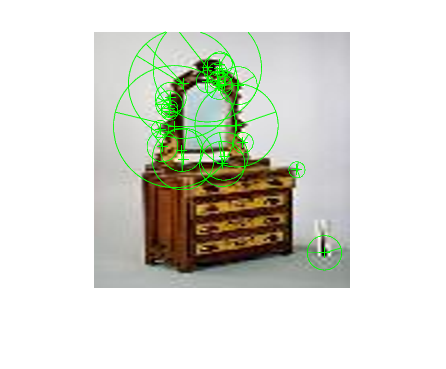

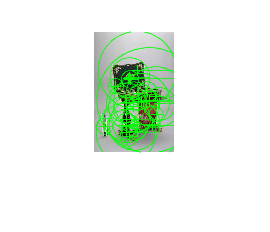

I = 256×256 uint8 matrix
   170   170   171   172   173   174   175   176   178   179   179   180   181   181   182   183   183   184   185   186   187   188   188   189   189   190   190   190   190   191   191   192   192   193   194   194   195   195   196   197   197   198   199   200   201   201   201   201   201   202
   170   170   171   172   173   174   175   176   178   179   179   180   181   181   182   183   183   184   185   186   187   188   188   189   189   190   190   190   190   191   191   192   192   193   194   194   195   195   196   197   197   198   199   200   201   201   201   201   201   202
   169   169   170   171   173   174   175   176   178   179   179   180   181   181   181   182   182   183   184   185   186   187   187   188   188   189   189   189   189   190   190   191   191   192   193   193   194   195   196   197   197   198   199   199   200   201   201   201   201   202
   169   169   170   171   173   174   175   176   178   179   179   180

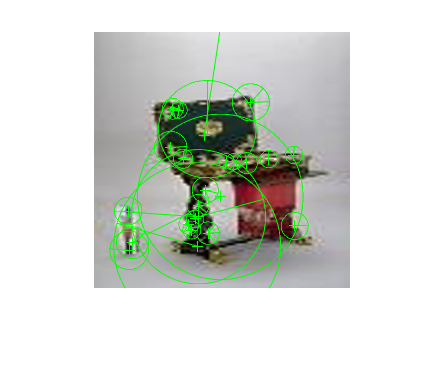

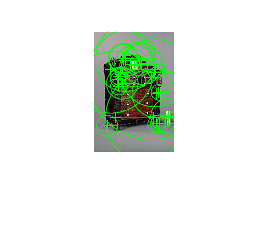

I = 256×256 uint8 matrix
   164   164   164   165   165   165   166   166   166   167   167   167   167   167   167   167   167   167   167   167   167   167   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166
   164   164   164   165   165   165   166   166   166   167   167   167   167   167   167   167   167   167   167   167   167   167   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166
   164   164   164   165   165   165   166   166   166   167   167   167   167   167   167   167   167   167   167   167   167   167   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166
   164   164   164   165   165   165   166   166   166   167   167   167

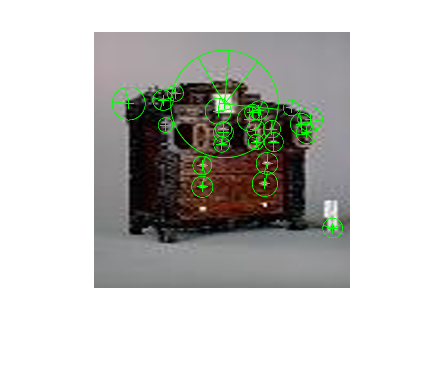

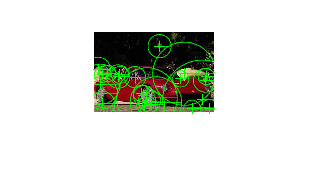

I = 256×256 uint8 matrix
   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   4   4   4   4   5   5   5   5   5   5   5   4   4   3   3   2
   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   4   4   4   4   5   5   5   5   5   5   5   4   4   3   3   2
   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   4   4   4   4   4   4   4   5   5   5   5   4   4   3   3   2
   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   4   4   4   4   3   3   3   3   2
   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   2   2   2   2   2   2   2   3   

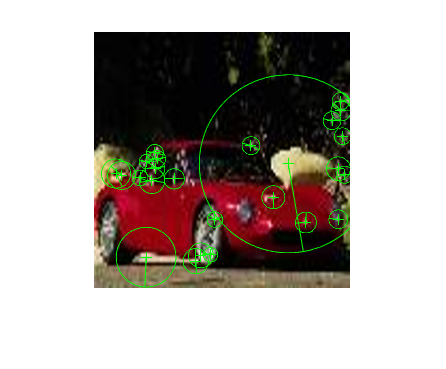

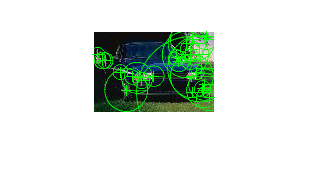

I = 256×256 uint8 matrix
   14   14   14   14   14   14   14   14   14   14   14   14   14   14   14   14   15   16   17   16   15   14   13   12   11   11   11   12   13   14   15   16   17   17   15   14   14   14   14   14   14   14   14   14   14   14   14   14   14   14
   14   14   14   14   14   14   14   14   14   14   14   14   14   14   14   14   15   16   17   16   15   14   13   12   11   11   11   12   13   14   15   16   17   17   15   14   14   14   14   14   14   14   14   14   14   14   14   14   14   14
   14   14   14   14   14   14   14   14   14   14   14   14   14   14   14   14   15   16   17   16   15   14   13   12   11   11   11   12   13   14   15   16   17   17   15   14   14   14   14   14   14   14   14   14   14   14   14   14   14   14
   14   14   14   14   14   14   14   14   14   14   14   14   14   14   14   14   14   16   17   16   15   14   13   12   11   11   11   12   13   14   15   15   17   17   15   14   14   14   14   14   14   14   14   14  

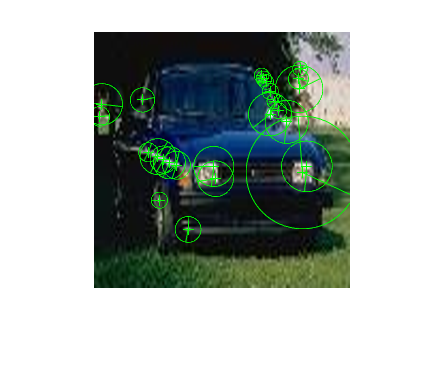

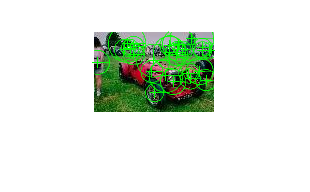

I = 256×256 uint8 matrix
   173   171   165   165   171   173   160   152   168   184   178   166   168   176   175   166   162   163   168   179   183   172   164   166   171   173   174   175   176   177   177   169   155   134   109    86    62    48    56    60    38    17    33    59    50    33    84   186   217   180
   173   171   165   165   171   173   161   153   167   182   177   166   168   175   174   167   164   164   168   177   181   172   165   166   170   173   175   175   174   174   172   162   147   127   104    82    59    45    52    56    36    17    33    58    50    34    80   172   201   170
   173   171   166   165   171   172   162   155   166   177   174   166   167   172   173   171   169   167   169   174   177   172   168   166   167   173   179   176   169   164   159   147   128   109    90    71    51    38    45    48    31    16    33    57    51    37    69   135   158   140
   172   171   167   166   170   171   164   159   163   168   168   166

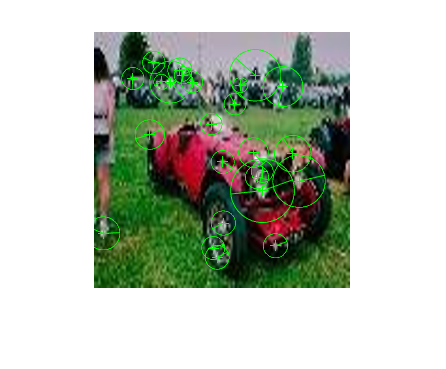

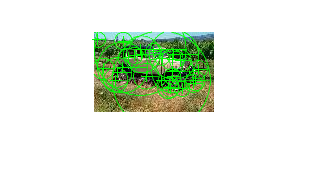

I = 256×256 uint8 matrix
   157   166   185   198   198   196   191   188   187   189   193   199   206   213   210   201   199   205   208   206   204   203   202   202   203   204   205   205   205   205   206   206   207   211   217   217   205   198   207   215   214   209   205   202   202   201   198   191   195   213
   160   168   185   196   196   195   192   190   189   190   193   198   205   212   210   201   200   206   208   206   204   203   202   202   203   204   205   205   205   205   206   206   207   210   215   215   204   199   207   215   213   208   205   202   203   204   201   194   197   211
   168   174   185   192   192   193   194   195   193   192   193   196   203   211   210   202   202   207   209   207   205   204   203   203   204   204   205   205   205   205   206   206   206   208   211   211   203   200   207   214   211   206   204   203   206   210   208   201   201   207
   180   182   184   186   187   189   196   202   201   196   194   193

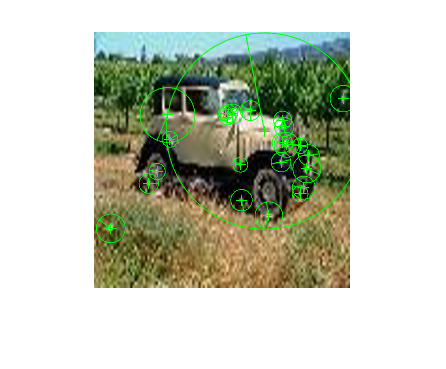

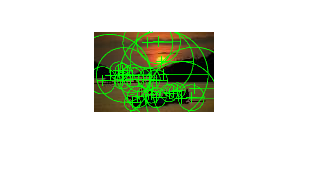

I = 256×256 uint8 matrix
   50   50   50   50   51   51   52   52   52   52   52   53   53   54   54   54   54   56   57   57   57   58   59   60   60   61   62   62   63   64   65   65   65   65   67   67   68   69   70   71   72   72   72   72   72   73   73   75   76   76
   50   50   50   50   51   51   52   52   52   52   52   53   53   54   54   54   54   56   57   57   57   58   59   60   60   61   62   62   63   64   65   65   65   65   67   67   68   69   70   71   72   72   72   72   72   73   73   75   76   76
   50   50   50   50   51   51   52   52   52   52   52   53   53   54   54   54   54   56   57   57   57   58   59   60   60   61   62   62   63   64   65   65   65   66   67   67   68   69   70   71   72   72   72   72   72   73   73   75   76   76
   51   51   51   51   52   52   53   53   53   53   53   54   54   55   55   54   55   56   57   58   58   59   60   61   61   62   63   63   64   65   66   66   66   66   67   68   69   70   71   71   72   72   72   73  

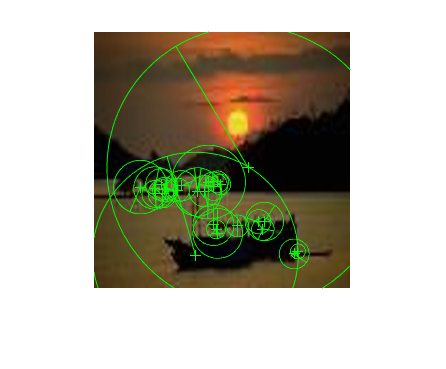

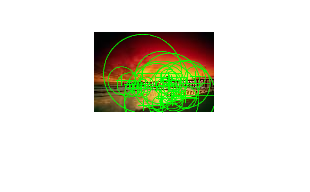

I = 256×256 uint8 matrix
   4   4   4   4   4   4   3   3   3   3   3   2   2   2   2   2   2   2   2   2   2   3   3   3   3   3   3   3   3   3   3   3   3   3   3   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2
   4   4   4   4   4   4   3   3   3   3   3   2   2   2   2   2   2   2   2   2   2   3   3   3   3   3   3   3   3   3   3   3   3   3   3   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2
   4   4   4   4   4   4   3   3   3   3   3   2   2   2   2   2   2   2   2   2   2   3   3   3   3   3   3   3   3   3   3   3   3   3   3   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2
   4   4   4   4   4   4   3   3   3   3   3   2   2   2   2   2   2   2   2   2   2   3   3   3   3   3   3   3   3   3   3   3   3   3   3   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2
   4   4   4   4   4   4   3   3   3   3   3   2   2   2   2   2   2   2   2   2   2   3   3   3   3   3   3   3   3   3   3   3   3   3   3   2   2   2   2   2   2   2   

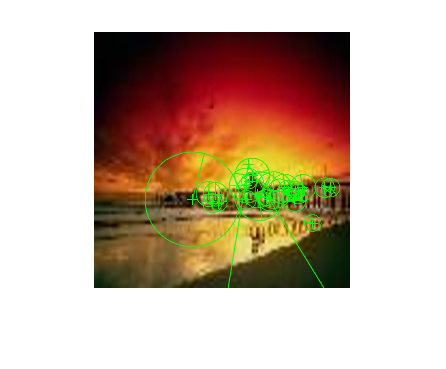

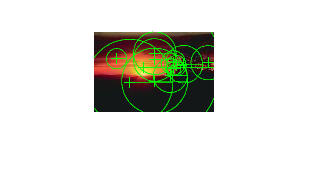

I = 256×256 uint8 matrix
    70    71    73    76    78    79    79    78    77    75    74    74    75    77    79    81    86    93    98    98    99   101   102   103   103   103   103   103   103   103   104   105   105   105   104   104   104   104   104   105   105   104   103   102   102   101   101   101   101   101
    70    71    73    76    78    79    79    78    77    75    74    74    75    77    79    81    86    92    97    97    98   100   101   102   102   102   102   102   102   102   103   104   104   104   104   104   104   104   104   104   104   103   103   102   102   101   101   101   101   101
    70    71    73    76    78    79    79    78    77    76    75    75    76    78    80    82    86    91    95    96    96    98    99   100   100   101   100   100   100   101   101   102   102   103   103   104   104   104   104   104   104   103   103   102   102   101   101   100   100   100
    71    72    74    77    78    79    79    79    78    77    76    76

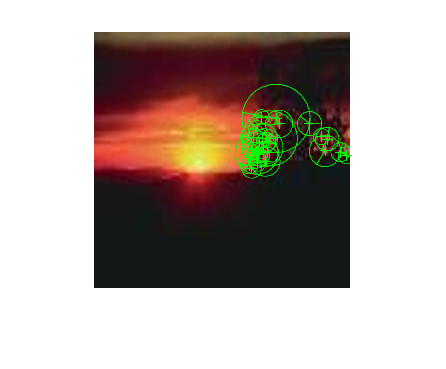

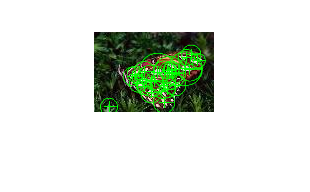

I = 256×256 uint8 matrix
   25   20   10    4    3    3    7    9    6    2    1    2   12   26   40   52   58   57   57   60   59   47   39   42   46   38   29   34   42   40   30   26   29   32   35   40   49   53   48   43   52   62   67   69   69   65   51   30   20   19
   24   20   10    4    3    4    7    9    6    3    2    4   13   28   41   53   58   56   56   59   59   48   39   39   42   36   30   34   39   36   27   25   29   32   33   37   47   52   47   43   51   60   65   66   66   62   49   29   19   19
   23   19   10    6    5    5    8   10    7    4    4    7   16   30   43   54   58   54   54   59   59   49   40   34   31   32   34   34   33   29   22   22   30   32   30   32   43   49   45   42   49   57   60   60   60   56   44   27   18   20
   22   19   11    7    7    8   10   11    8    6    7   11   21   34   46   56   58   51   50   58   60   52   40   26   17   26   39   34   23   16   13   18   30   33   24   23   35   45   43   40   46   52   53   51  

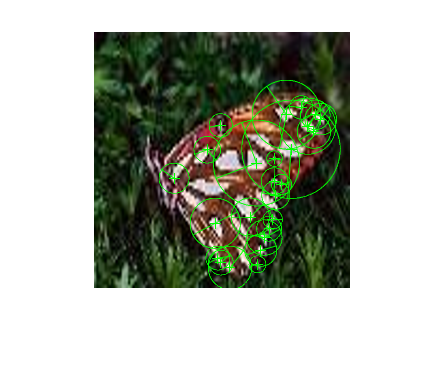

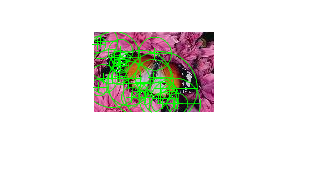

I = 256×256 uint8 matrix
   103   102    98    90    79    71    73    78    83    90    94   100   112   127   137   143   131   101    89   104   110    93    86   112   141   143   137   135   133   138   147   150   150   157   171   175   164   151   137   126   117   111   109   109   109   109   107   105   100    95
   101   101    99    94    83    75    77    81    86    93    96    99   109   121   129   133   123    96    85   100   106    92    87   110   136   139   134   133   133   137   144   148   149   155   167   170   160   148   135   125   117   112   111   111   111   111   108   105   100    94
    95    98   103   104    96    89    89    91    94    97    97    96    99   104   107   108   100    82    76    87    94    89    90   107   124   127   127   132   136   139   141   144   147   151   155   155   147   138   129   122   116   114   114   114   114   113   110   105   100    93
    87    94   110   118   115   110   107   106   106   105    99    90

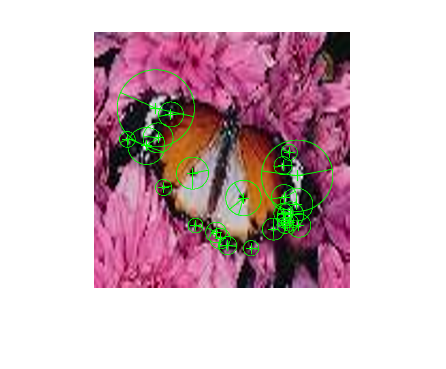

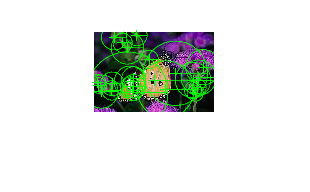

I = 256×256 uint8 matrix
    41    41    39    38    36    35    35    36    37    39    40    41    42    42    42    41    41    39    37    35    32    29    27    24    23    22    22    21    20    19    19    17    16    15    12    18    32    50    71    87    95    97    96    91    85    79    78    81    85    89
    41    41    39    38    36    35    35    36    37    39    40    41    42    42    42    41    41    39    37    35    32    29    27    24    23    22    22    21    20    19    19    17    16    15    12    18    33    51    71    86    94    96    95    90    84    79    78    81    85    89
    41    41    39    38    36    35    35    36    37    39    40    41    42    42    42    41    40    38    37    34    31    28    26    23    22    21    21    21    20    19    19    17    16    15    12    18    34    52    70    83    91    93    91    87    82    79    78    81    85    90
    40    40    39    37    36    35    35    36    37    39    40    41

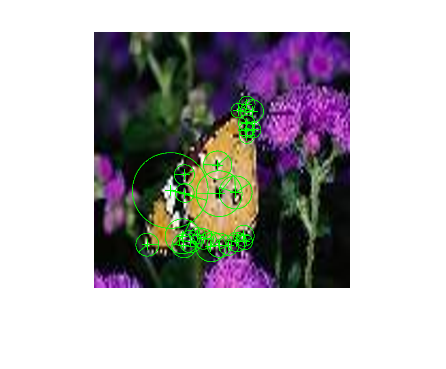

% display top 20 the matching images
for pic = 1 : min(20, length(ranks))
    if ranks(pic,2)>0
        % plot original image
        I = readimage(trainingSet, ranks(pic, 2));
        figure, imshow(I); hold on;
        sift = detectSIFTFeatures(im2gray(I)).selectStrongest(25);
        plot(sift,'showOrientation',true);

        % plot resized image
        I = imresize(I, [256 256]);
        figure, imshow(I); hold on
        I = im2gray(I);
        sift = detectSIFTFeatures(I).selectStrongest(25);
        [queryFeatures, valid_points] = extractFeatures(I, sift);
        plot(valid_points,'showOrientation',true);
    end
end